# H3 - Control de qualitat de peces de carn

### Inicialització de les bounding boxes i llindars manuals de les peces de carn

RECTS = [42, 159, 662, 272;
         54, 219, 650, 259;
         38, 187, 660, 284;
         68, 221, 618, 257;
         22, 167, 648, 258;
         34, 207, 632, 256;
         56, 227, 622, 249;
         30, 200, 654, 254;
         30, 209, 642, 242;
         32, 191, 654, 266;
         36, 221, 654, 248;
         32, 185, 676, 274;
         30, 197, 694, 256;
         22, 209, 656, 254];

% Llindars calculats manualment a partir dels histogrames de cada imatge
LLINDARS = [160; 190; 200; 195; 145; 160; 155; 185; 175; 170; 170; 170; 170; 160];

### Càlcul de percentatges de greix amb els diferents mètodes

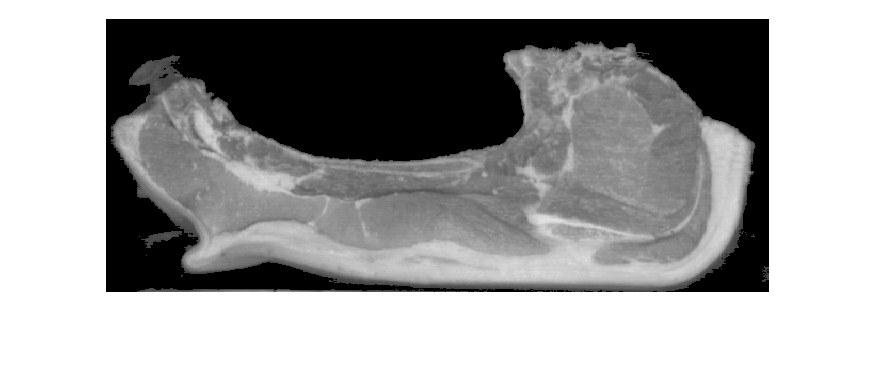

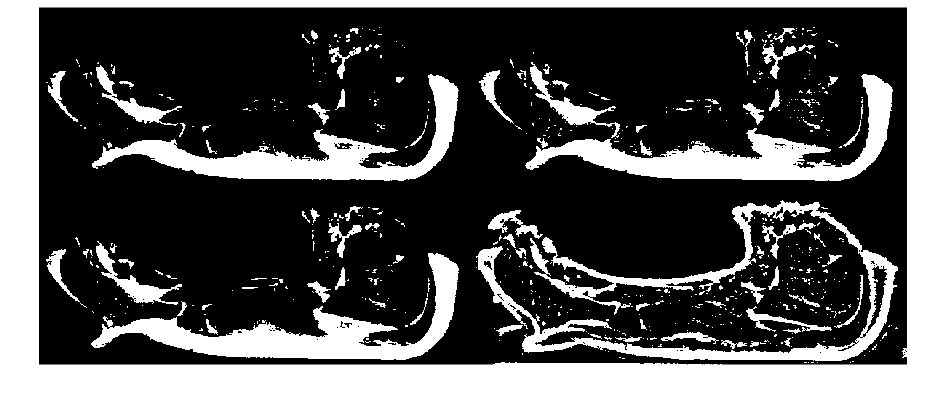

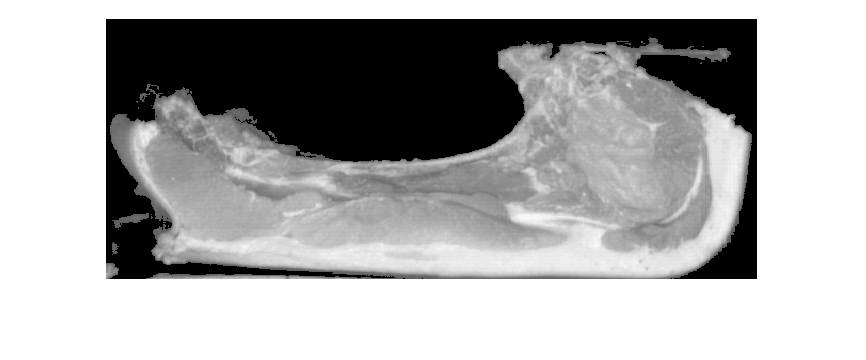

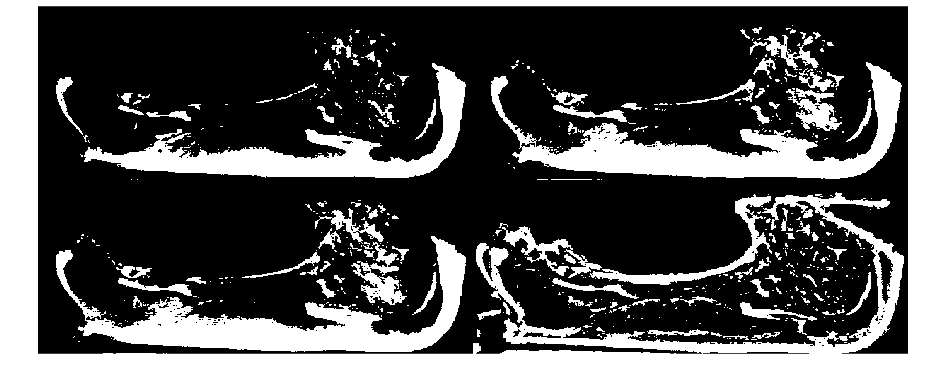

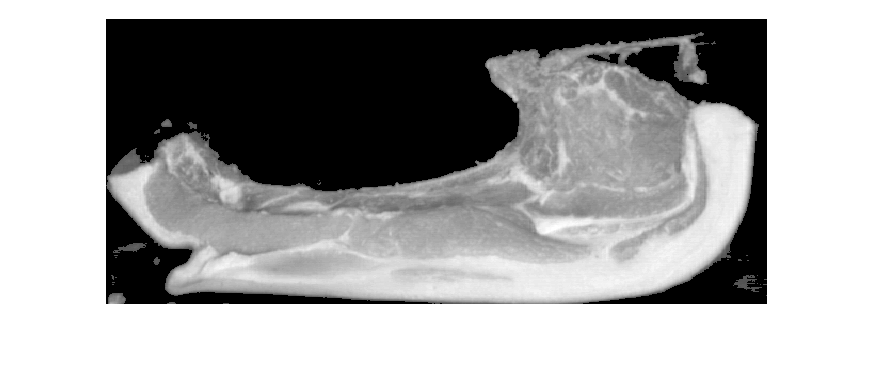

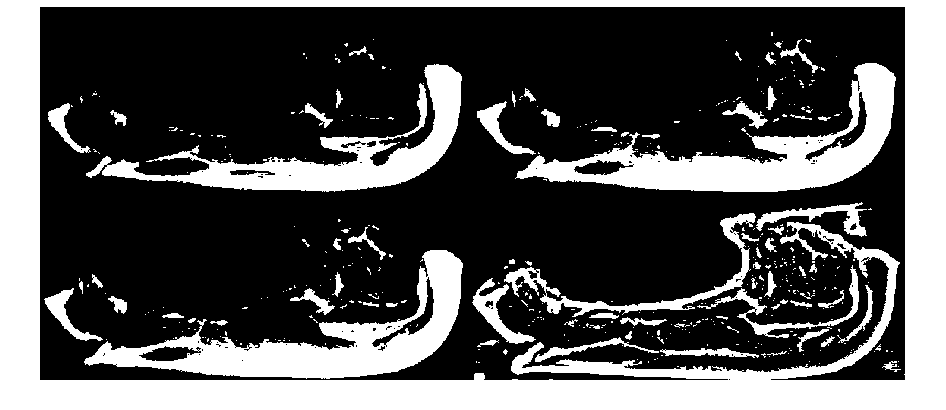

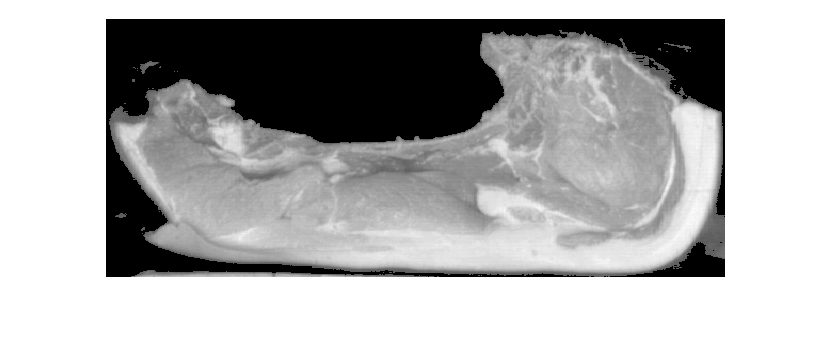

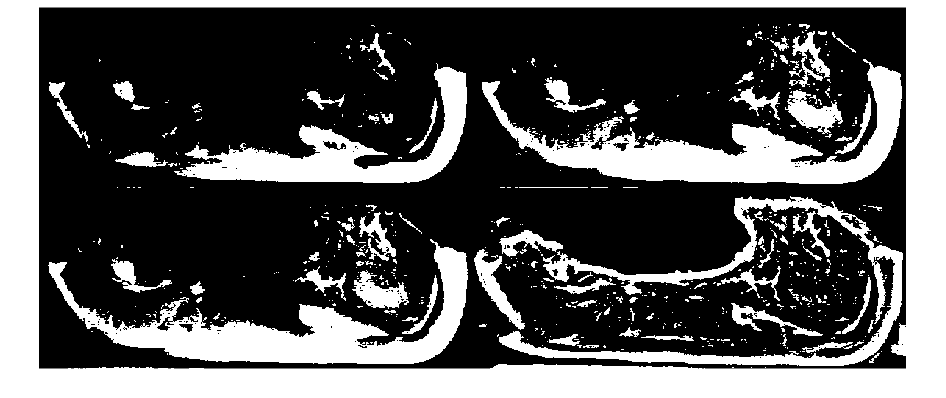

% script per obrir tots els arxius jpg d'una carpeta
close all
a = dir('./Chuletons/*.bmp');
nf = size(a);
PERCENTATGES = zeros(14, 4);
figure
for i = 1:nf 
    filename = horzcat(a(i).folder,'/',a(i).name);
    I = imcrop(imread(filename), RECTS(i, :));
    chuleton = treure_fons(I);
    figure
    imshow(chuleton);
    px_total = sum(sum(chuleton > 0));
    [greix_h, px_h] = obtenir_greix(chuleton, "histograma", LLINDARS(i));
    PERCENTATGES(i, 1) = px_h / px_total * 100;
    [greix_a, px_a] = obtenir_greix(chuleton, "automatic");
    PERCENTATGES(i, 2) = px_a / px_total * 100;
    [greix_o, px_o] = obtenir_greix(chuleton, "otsu");
    PERCENTATGES(i, 3) = px_o / px_total * 100;
    [greix_m, px_m] = obtenir_greix(chuleton, "moving");
    PERCENTATGES(i, 4) = px_m / px_total * 100;
    figure
    montage({greix_h, greix_a, greix_o, greix_m});
end

### Taula de percentatges

T = array2table(PERCENTATGES, "VariableNames", {'histograma', 'automatic', 'otsu', 'moving'}, "RowNames", {'1', '2', '3', '4', '5', '6', '7', '8', '9', '10', '11', '12', '13', '14'});
disp(T);

          histograma    automatic     otsu     moving
          __________    _________    ______    ______

    1       26.151       30.256      29.458    33.089
    2       26.946       38.666      37.634    35.555
    3       28.903       38.404       37.19    36.851
    4       23.756       38.879       37.24    32.833
    5       35.886       35.719      34.581    30.114
    6       25.677        30.83      28.832    34.061
    7       19.878       55.348      53.898    28.233
    8       13.241       36.674      34.969    34.907
    9       13.734       30.495      29.133    33.062
    10      17.116       31.036      29.684    35.284
    11      20.296       31.

### Funcions

function chuleton = treure_fons(I)
    % Fons tret amb el mètode graythresh
    llindar = graythresh(I) - 0.1;
    chuleton = imbinarize(I, llindar);
    chuleton = uint8(chuleton) .* I;
end

function [greix, px_greix] = obtenir_greix(I, option, llindar)
    if option == "histograma"
        % Amb llindar manual
        greix = I > llindar;
    elseif option == "automatic"
        % Amb llindar automatic, utilitzant graythresh
        llindar = graythresh(I(I > 0));
        greix = imbinarize(I, llindar);
    elseif option == "otsu"
        % Amb llindar automatic, utilizant el metode d'Otsu
        llindar = otsu(I);
        greix = I > llindar;
    elseif option == "moving"
        % Amb llindar automatic, utilitzant el metode de moving average
        window = [25, 25];
        llindar = colfilt(I, window, 'sliding', @mean);
        k = 10;
        greix = I > (llindar + k);
    end
    % Numero de pixels que corresponen a greix
    px_greix = sum(sum(greix > 0));
end

% Implementacio del metode d'Otsu
function llindar = otsu(I)
    [f, c] = size(I);
    % 1. Compute histogram and probabilities of each intensity level
    h = imhist(I);
    h(1) = 0;
    p = h/(f*c);
    m = (0:255) .* p';
    % 2. Initialize class probabilities w and class means mu
    w_0 = 0;
    mu_0 = 0;
    w_1 = 0;
    mu_1 = 0;
    % 3. Step through all possible thresholds t = 1 to 255
    llindar = 0;
    best_sigma = 0;
    for t=2:256
        w_0 = sum(p(1:t));
        mu_0 = sum(m(1:t))/w_0;
        w_1 = sum(p(t:256));
        mu_1 = sum(m(t:256))/w_1;
        sigma_b = w_0 * w_1 * (mu_0 - mu_1)^2;
        if (sigma_b > best_sigma)
            llindar = t;
            best_sigma = sigma_b;
        end
    end
end

### Resum dels mètodes utilitzats

El primer mètode que hem utilitzat per calcular el percentatge de greix ha sigut un mètode manual, és a dir, hem extret l'histograma de la imatge i posteriorment a ull hem extret el llindar. Hem repetit el procés per totes les peces de carn i els hem guardat al vector LLINDARS, que a continuació s'ha fet servir per calcular el greix de la carn.

A continuació, hem fet ús d'un mètode automàtic, és a dir, amb la funció graythresh aplicat als píxels més grans que 0 de la imatge (per tal de no considerar els píxels de fons) s'ha obtingut el llindar que posteriorment s'ha utilitzat per calcular la part de greix de la peça de carn.

Finalment, hem usat dos mètodes més per trobar el llindar. Per una banda, el mètode d'Otsu, implementat com s'ha explicat a classe, es pot observar que troba un llindar molt semblant a la funció graythresh. I, per una altra banda, el mètode d'average moving, on hem definit una finestra i hem calculat la mitjana de les finestres per tal d'obtenir el llindar.

A les imatges anteriors podem veure en primer lloc la imatge de la peça de carn seguit  d'un muntatge de 4 imatges, que representen la part de greix de la peça de carn obtingut amb els diferents mètodes. L'ordre és el següent: primera fila (manual, automàtic) i segona fila (Otsu, moving average).

Tots els percentatges de greix obtingut pels diferents mètodes es poden observar a la taula anterior i es pot apreciar que els tres primers mètodes donen resultats bastant semblants i identifiquen quasi les mateixes zones de greix. En canvi, amb el mètode de moving average dona una solució no massa bona i és bastant diferent que els resultats dels altres mètodes. S'ha provat amb diferents mides de finestra, però no s'ha pogut trobar una mida de finestra que millori els resultats. 

La conclusió a la qual hem arribat és que el mètode manual i els mètodes automàtics de graythresh i Otsu donen resultats més que acceptables i que el mètode de moving average no és una bona opció per aquest exercici.